# Solve Differential Equations in MATLAB

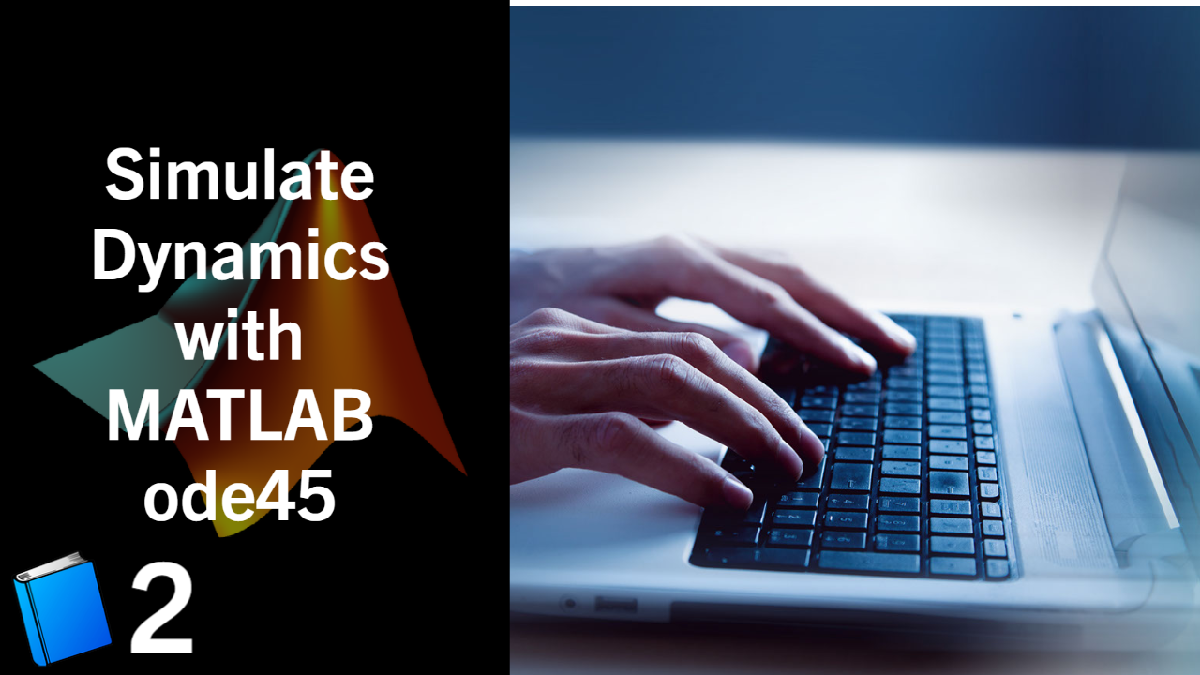

### [View Solution Video](https://youtu.be/ttQ8VzkXdYo)

## Solve an ODE with ode45

`ode45` numerically solves an ODE in the following form:

    `[t, y] = ode45(odefun, tspan, y0)`

**[t, y]** are the resulting y and time values from the ODE

**odefun** is the function that returns derivative values at the given time points

    `odefun` should be in the form: `function dydt = odefun(t,y)`

  When naming a function, use the syntax `@[function name]` to designate that a function is being referenced.

**tspan** is the time points for the function to be evluated at

**y0** is the initial value of the function at the first time point

#### If multiple arguments are required for the function:

For functions with more than one variable  returned (for example a and b), package these in a collumn vector c and make the function return c. See video solution for more information.

        `odefun(t, y, a, b, c)`

        `[t,y] = ode45(@(t,y) odefun(t,y,a,b,c), tspan, ic)`

`    Here, the @(t,y) odefun(t,y,a,b,c) `portion of the code creates an anonymous function that returns `t` and `y`, but accepts all the arguments required for the odefun.

### Case 1: There are multiple integrated variables

We will solve the following example and discuss it.


$$\frac{dx}{dt} = -y \\
\frac{dy}{dt} = x\\
x(0)  = 1\\
y(0) = 1 $$


Add initial conditions:

tspan = [0 10];
initial_conditions = [1; 1]; 

Note that initial conditions and results from the differential function should be column vectors denoted by the ; after each row.

Simulate:

[t, z] = ode45(@example_1, tspan, initial_conditions)

See example_1 function at the bottom of the page for the function itself.

Unpack Z array to individual results arrays and graph:

x = z(:,1);
y = z(:,2);
plot(t, [x, y])
title('Example 1')
legend("x", "y")


Here, both $\frac{dx}{dt}$ and $\frac{dy}{dt}$ were packed in the column vector z. This allowed for each to be calculated with the other's value, and for both to integrate over time. The result array, `z` has a column for each variable integrated, and a row for each time point. 

### Case 2: There is a change to one or more inputs during the simulation

If this is the case, we must use a loop to calculate the change within each time step. This allows for different inputs or arguments to be calculated at each time step. In the below example, u changes with time. Observe how this is handled:


$$\frac{dy}{dt} = -5+u*e^t\\
y(0) = 0\\
{u = 1 \text{ when } t<5\\
u=0\text{ otherwise}$$


Use n to control the length of the simulation:

Create u input array:

Create other Storage arrays

Initial conditions

Plot results

#### Exercise 1:

viewSolution1(false)


$$\frac{dy(t)}{dt} =  -y(t) + 1$$
 

From 0 to 10 seconds 


$$y(0) = 0$$


#### Exercise 2:

viewSolution2(false)


$$5\frac{dy}{dt}=-y(t) + u(t)\\
y(0) = 1\\
u(t) = 2s(t-10)
$$


#### Exercise 3:

viewSolution3(false)


$$\frac{dx(t)}{dt} = 3e^{-t}\\
 \frac{dy(t)}{dt}= 3-y(t)\\
x(0) = y(0) = 0$$


#### Exercise 4:

viewSolution4(false)


$$2\frac{dx(t)}{dt} = -x(t)+u(t)$$



$$5\frac{dy(t)}{dt}=-y(t) + x(t)$$



$$u=2s(t-5)\\
x(0)=0\\
y(0)=0$$


### Add Functions Below

function viewSolution1(view)
if view
disp("clc; clear all; close all;" + newline + ...
     "% Note that funcitons must appear at the bottom " + newline + ...
     "time = [0 5]; % Time points" + newline + ...
     "y0 = 0; % initial value" + newline + ...
     "" + newline + ...
     "[tm, y] = ode45(@ode_ex1, time, y0);" + newline + ...
     "" + newline + ...
     "figure(1)" + newline + ...
     "plot(tm, y)" + newline + ...
     "title('Exercise 1')" + newline + ...
     "" + newline + ...
     "--- snip ---" + newline + ...
     "function dydt = ode_ex1(t, y)" + newline + ...
     "    dydt = -y + 1;" + newline + ...
	 "end")
end
end

function viewSolution2(view)
if view
disp("% plot y" + newline + ...
     "[tm, y] = ode45(@ode_ex2, [0, 40], 1);" + newline + ...
     "" + newline + ...
     "% plot u" + newline + ...
     "n = 40;" + newline + ...
     "u_time = linspace(0, n, n+1);" + newline + ...
     "u = zeros(1, n+1);" + newline + ...
     "u(10:end) = 2;" + newline + ...
     "" + newline + ...
     "figure(2)" + newline + ...
     "plot(tm, y)" + newline + ...
     "title('Exercise 2')" + newline + ...
     "hold on" + newline + ...
     "plot(u_time, u)" + newline + ...
     "legend({'Y', 'U'})" + newline + ...
     "hold off" + newline + ...
     "" + newline + ...
     "--- snip ---" + newline + ...
     "function dydt = ode_ex2(t, y)" + newline + ...
     "if t > 10" + newline + ...
     "    u = 2;" + newline + ...
     "else" + newline + ...
     "    u = 0;" + newline + ...
     "end" + newline + ...
     "    dydt = (-y + u)/5;" + newline + ...
	 "end")
end
end

function viewSolution3(view)
if view
disp("[t, z] = ode45(@ode_ex3, [0,20], [0, 0]);" + newline + ...
     "" + newline + ...
     "x = z(:,1);" + newline + ...
     "y = z(:,2);" + newline + ...
     "plot(t, x, 'ro')" + newline + ...
     "title('Exercise 3')" + newline + ...
     "hold on" + newline + ...
     "plot(t, y, 'b-')" + newline + ...
     "legend({'X','Y'})" + newline + ...
     "hold off" + newline + ...
     "--- snip ---" + newline + ...
     "function dzdt = ode_ex3(t, z)" + newline + ...
     "    x = z(1);" + newline + ...
     "    y = z(2);" + newline + ...
     "    dxdt = 3 * exp(-t);" + newline + ...
     "    dydt = 3 - y;" + newline + ...
     "    dzdt = [dxdt; dydt];  % note that for multiple outputs, must return column vector" + newline + ...
	 "end")
end
end

function viewSolution4(view)
if view
disp("% create u array" + newline + ...
     "n = 20;" + newline + ...
     "u = zeros(1, n+1);" + newline + ...
     "u(5:end) = 2;" + newline + ...
     "" + newline + ...
     "% initialize storage arrays" + newline + ...
     "x = zeros(1, n+1);" + newline + ...
     "y = zeros(1, n+1);" + newline + ...
     "z0 = [0; 0];  % initial conditions" + newline + ...
     "time = linspace(0, n, n+1);" + newline + ...
     "" + newline + ...
     "% simulate" + newline + ...
     "for i = 1:n" + newline + ...
     "    [tm, z] = ode45(@(t,z) ode_ex4(t, z, u(i)), [0, 1], z0);" + newline + ...
     "    z0 = z(end, :);" + newline + ...
     "    x(i+1) = z0(1);" + newline + ...
     "    y(i+1) = z0(2);" + newline + ...
     "end" + newline + ...
     "" + newline + ...
     "% graph" + newline + ...
     "plot(time, x)" + newline + ...
     "title('Exercise 4')" + newline + ...
     "hold on" + newline + ...
     "plot(time, y)" + newline + ...
     "legend({'X', 'Y'});" + newline + ...
     "hold off" + newline + ...
     "--- snip ---" + newline + ...
     "function dzdt = ode_ex4(t, z, u)" + newline + ...
     "    x = z(1);" + newline + ...
     "    y = z(2);" + newline + ...
     "    " + newline + ...
     "    dxdt = (-x+u)/2;" + newline + ...
     "    dydt = (-y+x)/5;" + newline + ...
     "    dzdt = [dxdt; dydt];" + newline + ...
	 "end")
end
end